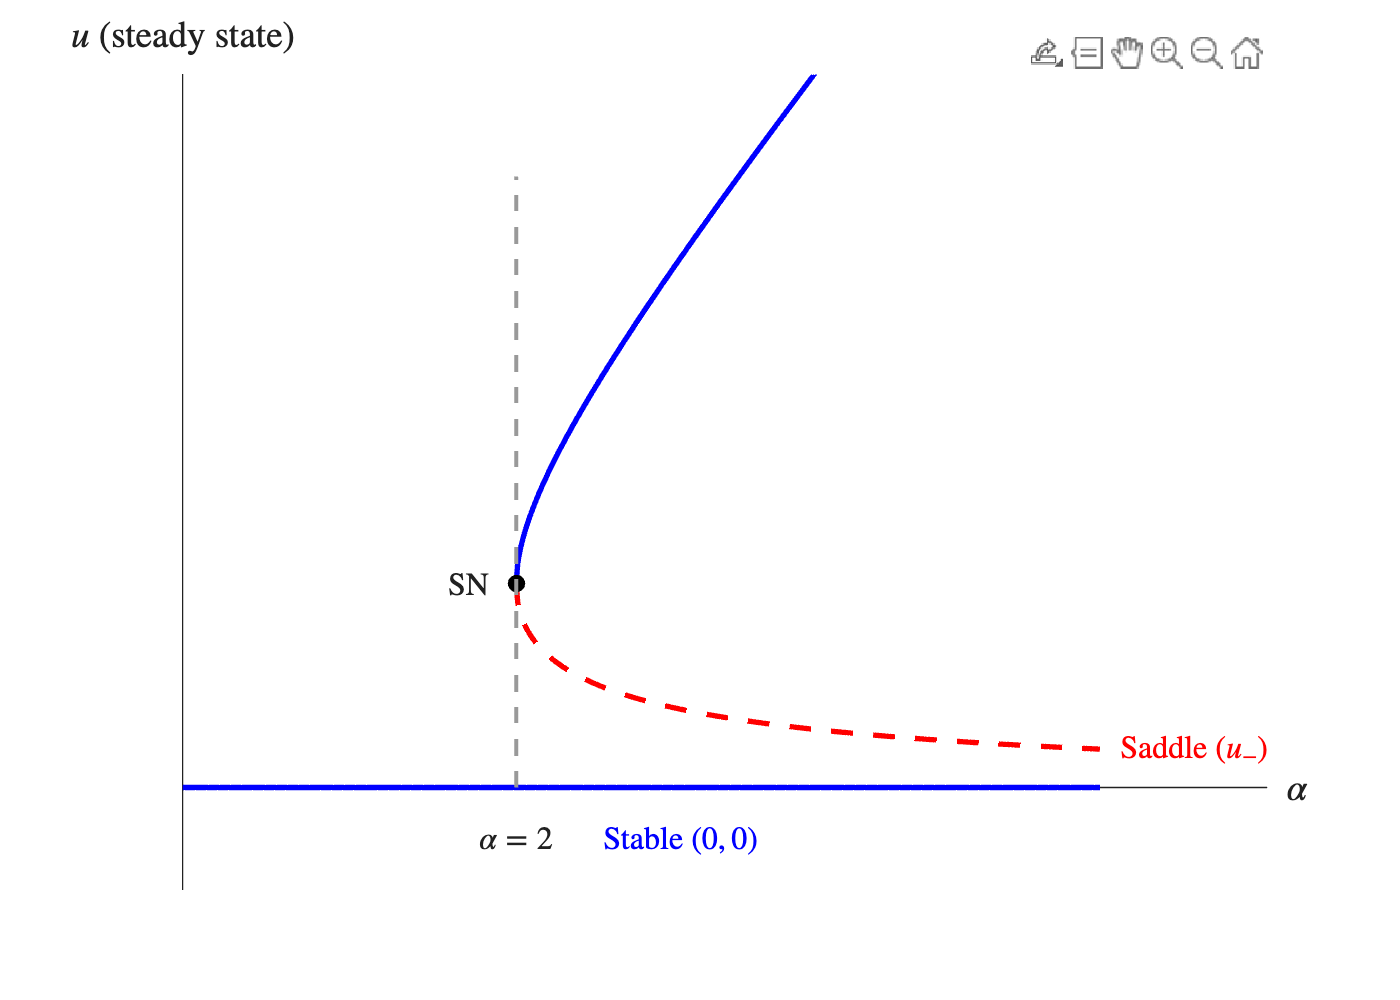

% MATLAB script to plot the Bifurcation Diagram for the Toggle Switch
% Control parameter: alpha (dimensionless production rate)
% State variable: u (dimensionless concentration)

clear; clc; close all;

% 1. Define the range for the control parameter alpha
alpha_full = linspace(0, 5.5, 500);      % Full range for the trivial solution
alpha_bif = linspace(2, 5.5, 400);       % Range where non-trivial roots exist (alpha >= 2)

% 2. Calculate the steady-state branches
% Trivial branch: u = 0 for all alpha
u_trivial = zeros(size(alpha_full));

% Non-trivial branches (from u^2 - alpha*u + 1 = 0)
u_plus = (alpha_bif + sqrt(alpha_bif.^2 - 4)) / 2;  % Upper branch
u_minus = (alpha_bif - sqrt(alpha_bif.^2 - 4)) / 2; % Lower branch

% 3. Create the figure and plot the branches
figure('Position', [150, 150, 700, 500], 'Color', 'w');
hold on;

% Plot stable branches as solid blue lines
plot(alpha_full, u_trivial, 'b-', 'LineWidth', 2);
plot(alpha_bif, u_plus, 'b-', 'LineWidth', 2);

% Plot unstable branch as a dashed red line
plot(alpha_bif, u_minus, 'r--', 'LineWidth', 2);

% 4. Add the Saddle-Node (SN) bifurcation marker and dashed line
plot(2, 1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6); % SN dot
plot([2, 2], [0, 3], 'Color', [0.6 0.6 0.6], 'LineStyle', '--', 'LineWidth', 1.5);

% 5. Add text labels matching the diagram
% We use the 'latex' interpreter so the math fonts look perfect
text(1.9, 1, 'SN ', 'HorizontalAlignment', 'right', 'FontSize', 12, 'Interpreter', 'latex');
text(2, -0.25, '$\alpha=2$', 'HorizontalAlignment', 'center', 'FontSize', 12, 'Interpreter', 'latex');
text(5.6, u_plus(end), 'Stable Node ($u_+$)', 'Color', 'b', 'FontSize', 12, 'Interpreter', 'latex');
text(5.6, u_minus(end), 'Saddle ($u_-$)', 'Color', 'r', 'FontSize', 12, 'Interpreter', 'latex');
text(2.5, -0.25, 'Stable $(0,0)$', 'Color', 'b', 'FontSize', 12, 'Interpreter', 'latex');

% 6. Format the axes to match the clean, "textbook" style
xlim([0, 6.5]);
ylim([-0.5, 3.5]);

% Move the x and y axes to the origin
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
box off;

% Remove default tick marks to mimic the theoretical sketch
ax.XTick = [];
ax.YTick = [];

% Add axis labels manually since we moved the axes to the origin
text(6.6, 0, '$\alpha$', 'FontSize', 14, 'Interpreter', 'latex');
text(0, 3.7, '$u$ (steady state)', 'HorizontalAlignment', 'center', 'FontSize', 14, 'Interpreter', 'latex');

hold off;